# **(D) Actividad Aprendizaje Profundo.**

Este ejemplo muestra como estimar la postura para una o mas personas usando el algortimo OpenPose y una red neuronal pre-entrenada.

El objetivo es estimar la ubicación de las personas y la orientación de las partes de su cuerpo. 

Hay dos estrategias principales de estimacion de postura: top-down y bottom-up.

This example shows how to estimate the body pose of one or more people using the OpenPose algorithm and a pretrained network.

OpenPose es un algoritmo para estimacion de múltiples personas que usa una estregia bottom-up [1]. OpenPose estima heatmaps que indican la probabilidad que una parte específica del cuerpo este asociada a un pixel. También OpenPose estima los part affinity fields (PAFs), que son campos vectoriales que indican si dos segmentos del cuerpo estan conectados o no. Por cada par de segmentos conectados, por ejemplo cuello y hombros, hay dos PAFs hay 2 PAFs que muestran las componentes x- y y- de los campos vectoriales entre los segmentos.

Para obtener una pose completa, OpenPose realiza operaciones de post-procesamiento. Primero identificando los segmentos corporales en base a los heatmaps. Luego, mediante operaciones sucesivas identifica conexiones entre segmentos del curspo. Para más información puede ver el algoritmo en Identify Poses from Heatmaps and PAFs.

## Importar la red neuronal

Importa la red ya entrenada en formato ONNX.

dataDir = fullfile(tempdir,"OpenPose");

trainedOpenPoseNet_url = "https://ssd.mathworks.com/supportfiles/"+ ...
    "vision/data/human-pose-estimation.zip";
downloadTrainedOpenPoseNet(trainedOpenPoseNet_url,dataDir)

Pretrained OpenPose network already exists.



unzip(fullfile(dataDir,"human-pose-estimation.zip"),dataDir);

Puede requerir instalar el Deep Learning Toolbox™ Converter for ONNX Model Format, si es asi, siga las instrucciones del error.

modelfile = fullfile(dataDir,"human-pose-estimation.onnx");
net = importNetworkFromONNX(modelfile);

Saca las capas de salida de la red.

net = removeLayers(net,net.OutputNames);

Inicializa la red usando un vector de entrada aleatorio.

inputSize = net.Layers(1).InputSize;
X = dlarray(rand(inputSize),"SSC");
net = initialize(net,X);

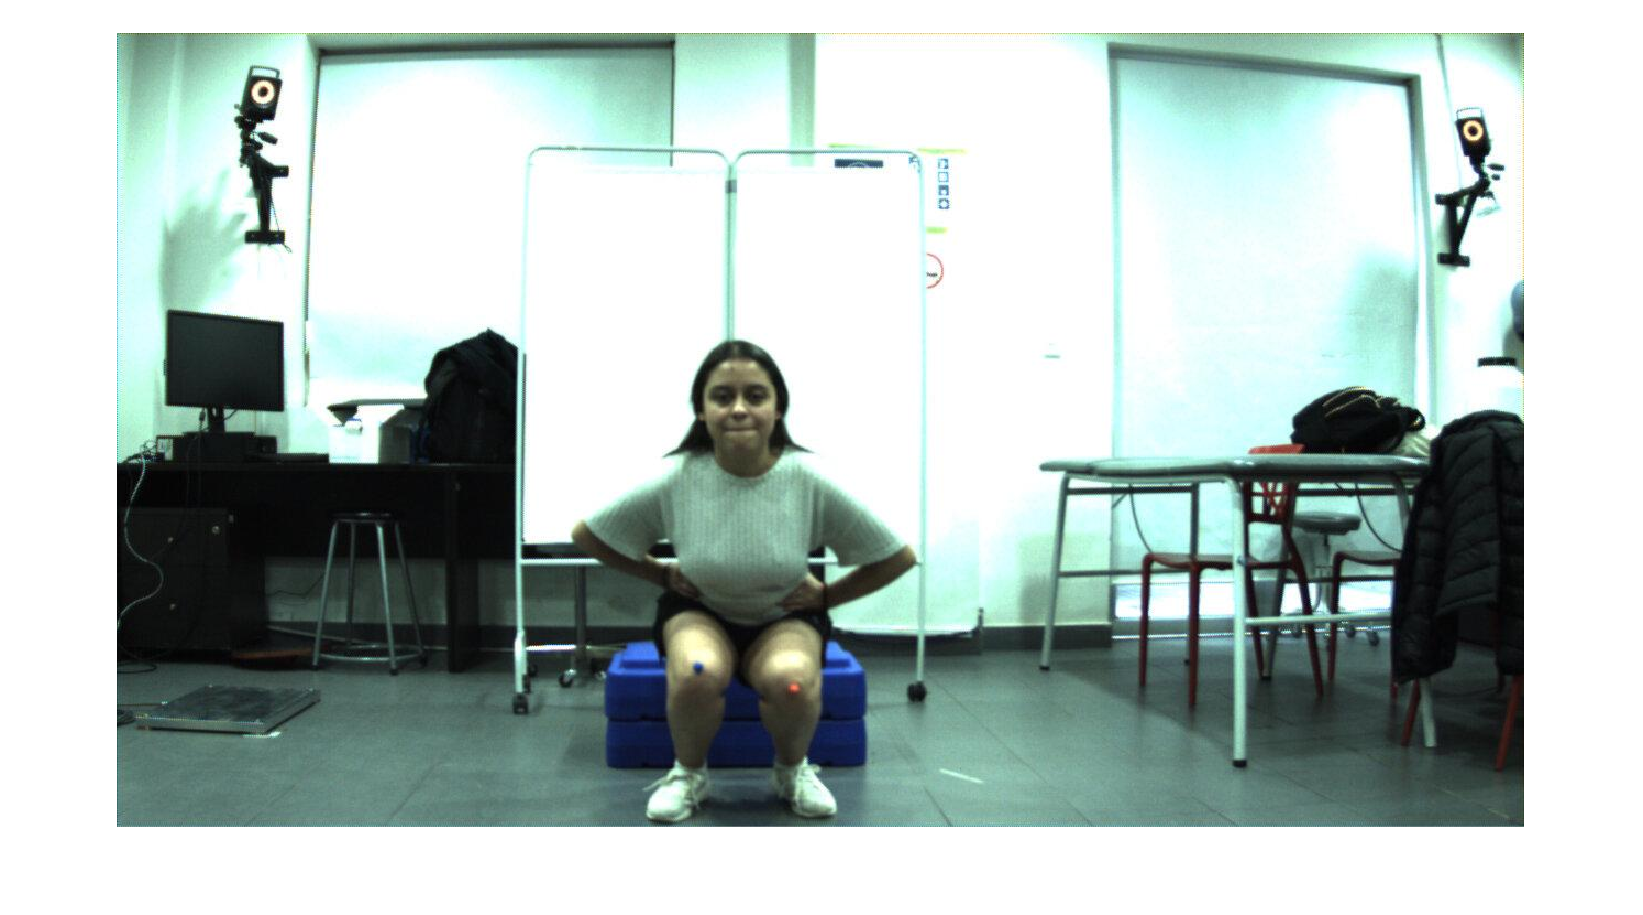

obj = VideoReader('../data/videoejemplo.avi');
im = read(obj,40);

imshow(im)

## Predecir Heatmaps y PAFs en la imagen de prueba

Re-escalamos la imagen en el rango [-0.5, 0.5] (como fue entrenada)

netInput = im2single(im)-0.5;

La red se entrego en el orden BGR, asi que cambiamos el orden de los canales.

netInput = netInput(:,:,[3 2 1]);

Cambiamos la estructura de almacenamiento de datos.

netInput = dlarray(netInput,"SSC");

Predicción de heatmaps y part affinity fields (PAFs), las salidas de las capas de convolución 2-D.

[heatmaps,pafs] = predict(net,netInput);

Obtener resultado número desde el `dlarray`. Son 19 canales. Cada canal es un segmento del cuerpo y se agrega el fondo.

heatmaps = extractdata(heatmaps);

Visualización de los heatmaps cambiando la escala a [0, 1].

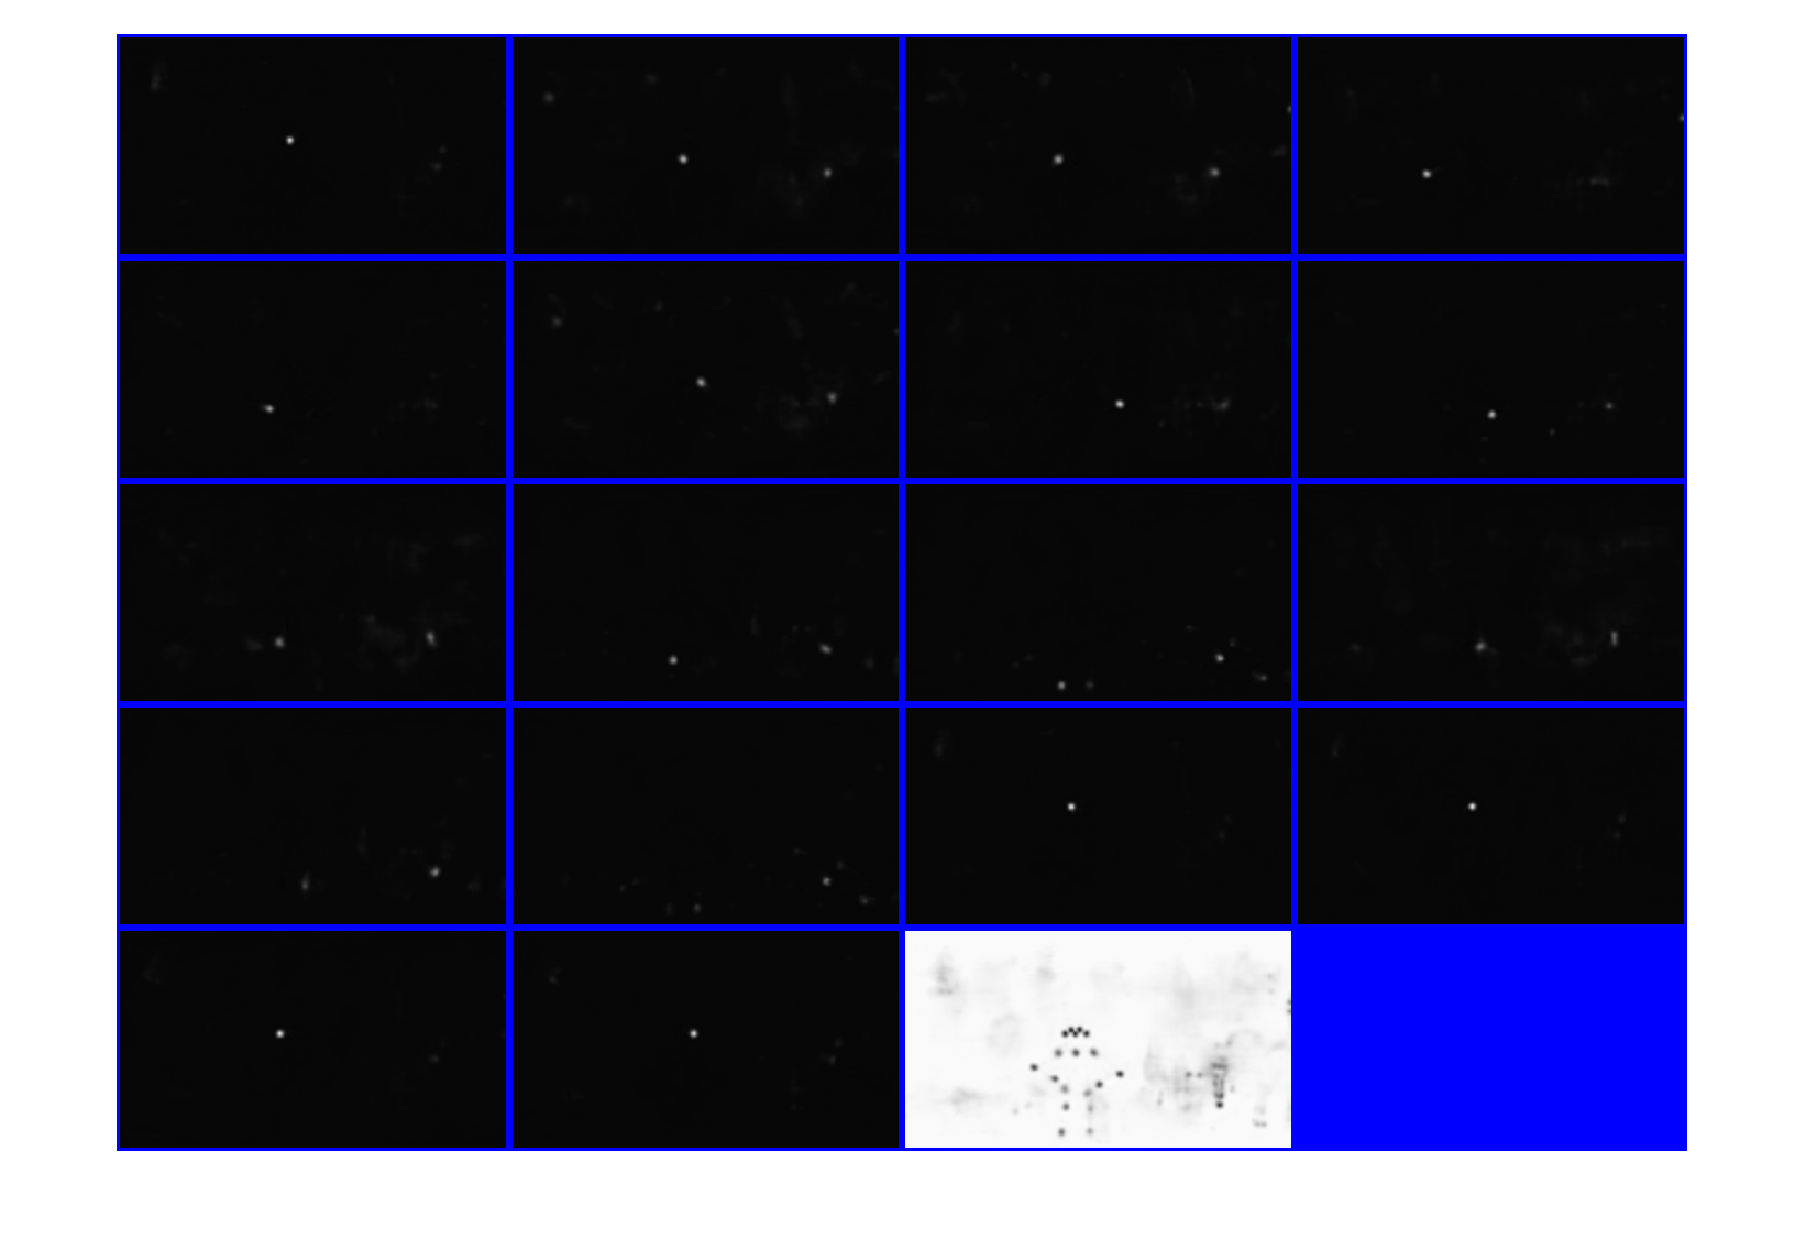

montage(rescale(heatmaps),BackgroundColor="b",BorderSize=3)

Para que se vea mejor visualizamos heatmap encima de la imagen de prueba.

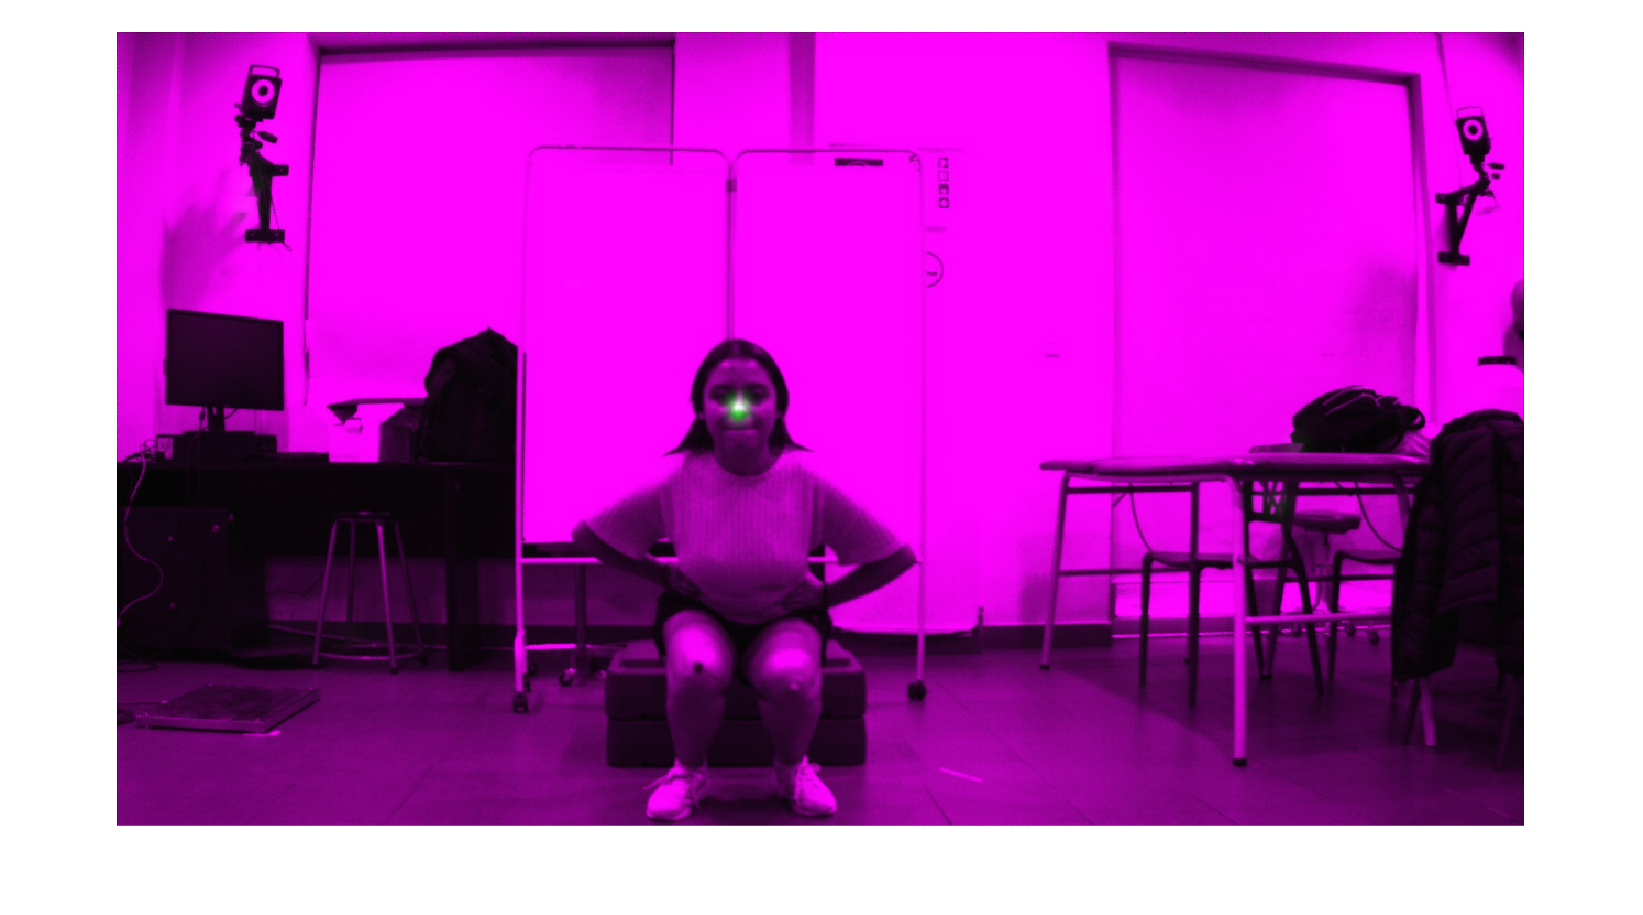

idx = 1;
hmap = heatmaps(:,:,idx);
hmap = imresize(hmap,size(im,[1 2]));
imshowpair(hmap,im);

OpenPose no usa el heatmap del fondo asi que se puede eliminar.

heatmaps = heatmaps(:,:,1:end-1);

Obtener los PAFs desde la estructura de datos `dlarray`. Son 38 canales. Son dos canales para cada par de segmentos del cuerpo, cada uno representa las componentes x e y del campo vectorial.

pafs = extractdata(pafs);

Los segmentos que tienen conexiones principalmente verticales tienen una magnitud mayor en la componente y, de manera analoga si las conexiones son principalmente en el eje x. Por ejemplo la cadera con la rodilla derecha (segunda fila). Notar que esto depende de la postura.

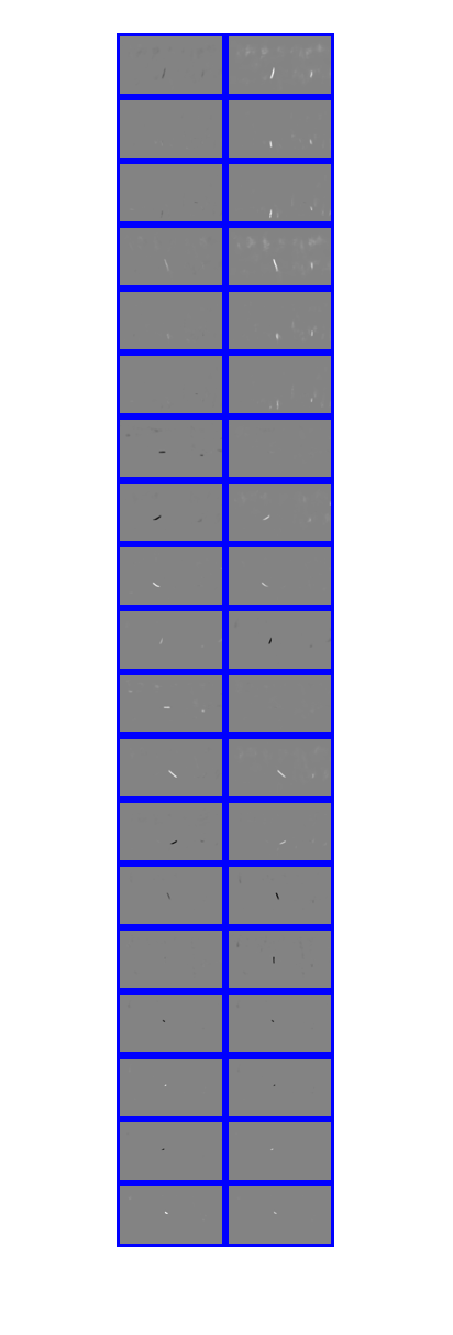

montage(rescale(pafs),Size=[19 2],BackgroundColor="b",BorderSize=3)

## Identificar postura desde Heatmaps y PAFs

Parametros de configuración de la detección de partes del cuerpo.

params = getBodyPoseParameters;

La función auxiliar entrega una matriz 3-D. La primera dimensión representa la cantidad de personas identificadas en la imagen. La segunda dimensión el número de partes del cuerpo. La tercera dimensión entrega la posición de parte del cuerpo. Si un segmento no se detecta, aparecera [NaN NaN].

poses = getBodyPoses(heatmaps,pafs,params);

Muestra el resultado usando la función auxiliar `renderBodyPoses.`

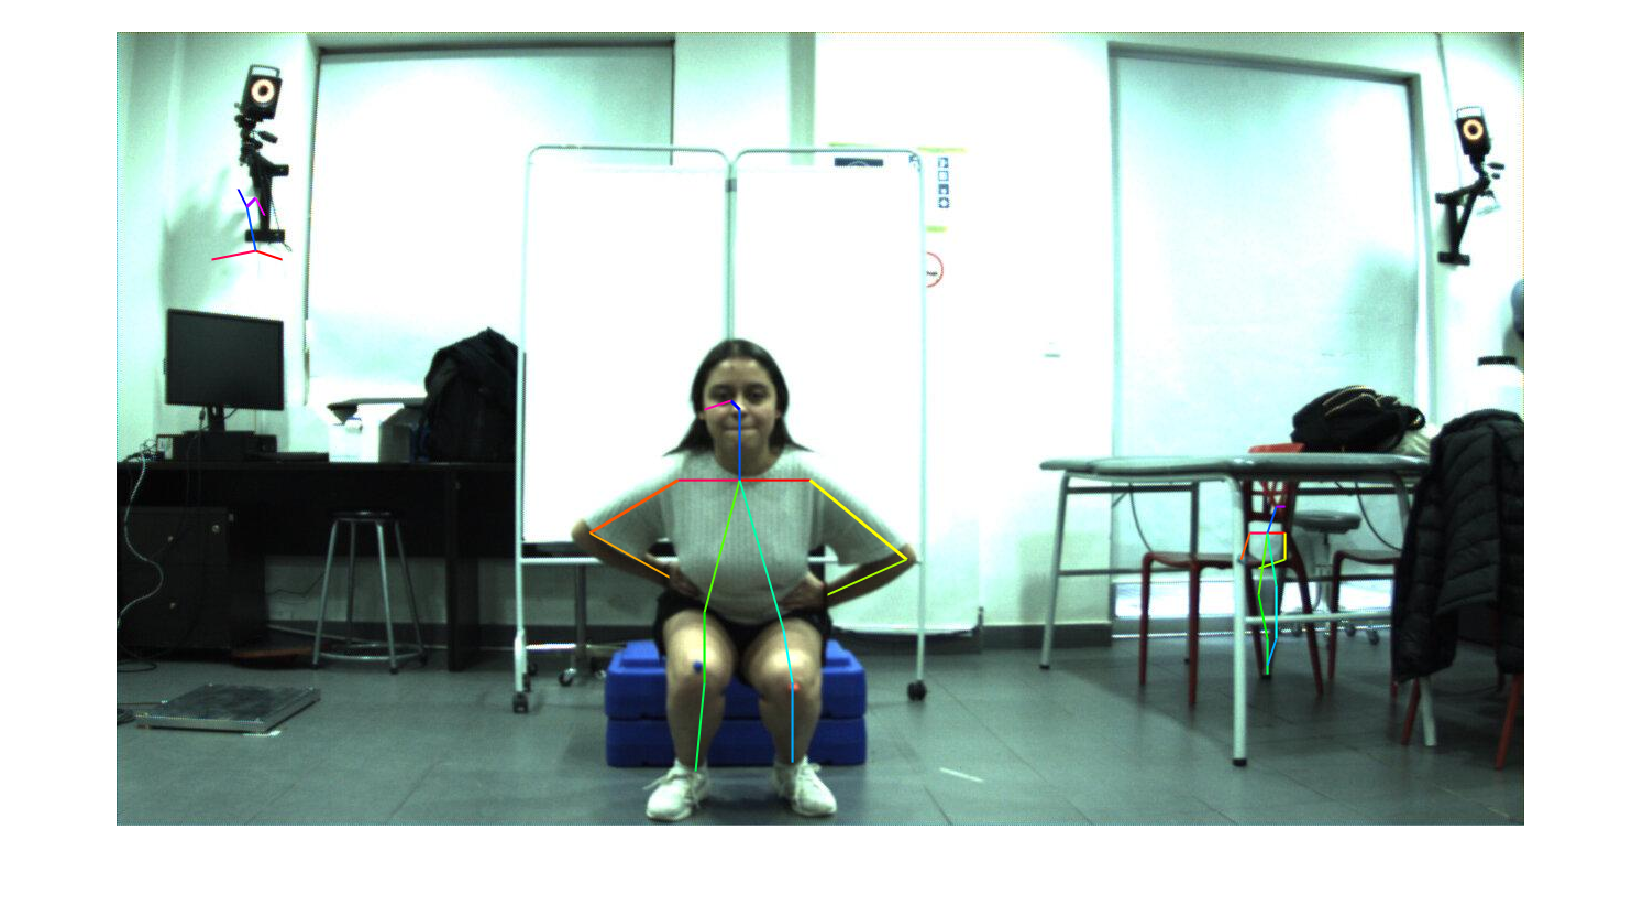

output=renderBodyPoses(im,poses,size(heatmaps,1),size(heatmaps,2),params);

## References

[1] Cao, Zhe, Gines Hidalgo, Tomas Simon, Shih-En Wei, and Yaser Sheikh. “OpenPose: Realtime Multi-Person 2D Pose Estimation Using Part Affinity Fields.” *ArXiv:1812.08008 [Cs]*, May 30, 2019. [https://arxiv.org/abs/1812.08008](https://arxiv.org/abs/1812.08008).

[2] Osokin, Daniil. “Real-Time 2D Multi-Person Pose Estimation on CPU: Lightweight OpenPose.” *ArXiv:1811.12004 [Cs]*, November 29, 2018. [https://arxiv.org/abs/1811.12004](https://arxiv.org/abs/1811.12004).

*Basado en un ejemplo Copyright 2020-2024 The MathWorks, Inc.*